clear all

## Problem b

% System time (characteristic time)
t0 = 0;
tf = 6.5; % initial tf guess
uMax = 0.1;

% Planet Initializing
aEarth = 1; % semimajor axis, AU
vEarth = 0; % true anomaly, rad
aMars = 1.524; % semimajor axis, AU
vMars = pi; % true anomaly, rad
mu = 1; % using characteristic time and length

% Planetary motion
velEarth = sqrt(mu / aEarth^3); % angular velocity
velMars = sqrt(mu / aMars^3); % angular velocity
posEarth = @(t) aEarth * [cos(vEarth + velEarth*t), sin(vEarth + velEarth*t)].'; % propagate earth
posMars = @(t) aMars * [cos(vMars + velMars*t), sin(vMars + velMars*t)].'; % propagate mars

% Spacecraft initializing
r0 = [aEarth, 0].'; % initial position
v0 = [0, aEarth * velEarth].'; % initial velocity

lamd0Init = [5;2;2;7]; % initialize costate vector
Z0 = [lamd0Init; tf];

% Define ODE
function XDot = spacecraftODE(t, X, mu, uMax)
    r = X(1:2); % position
    v = X(3:4); % velocity
    
    lamdr = X(5:6); % position costate
    lamdv = X(7:8); % velocity costate

    %epsn = 1e-12;
    %if norm(lamdv) < epsn
    %    u = [0;0];
    %else
        u = -uMax * (lamdv / norm(lamdv));
    %end

    rDot = v; % derivative r
    vDot = -mu * r / norm(r)^3 + u; % derivative v

    lamdrDot = -mu * ((3*(r*r')/norm(r)^5 - eye(2)/norm(r)^3) * lamdv); % derivative pos costate
    lamdvDot = -lamdr; % derivative vel costate

    XDot = [rDot; vDot; lamdrDot; lamdvDot]; % STATE ODE
end

% Define SHOOTING FUNCTION
function residual = shooting(Z, posMars, t0, r0, v0, uMax, mu, velMars)
    lamd0 = Z(1:4);
    tf = Z(5);
    if tf <= 0
        residual = 1e6*ones(5,1);
        return
    end

    X0 = [r0; v0; lamd0]; % initial state
    tSpan = linspace(t0,tf,10000); % time span
    options = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
    try
        [~, X] = ode45(@(t, X) spacecraftODE(t,X,mu,uMax), tSpan, X0, options); % ODE solver
    catch
        residual = 1e6*ones(5,1);
        return
    end

    rf = X(end, 1:2)'; % FINAL position
    vf = X(end, 3:4)';
    lamdrf = X(end, 5:6)';
    lamdvf = X(end, 7:8)';

    posMarsf = posMars(tf);
    velMarsf = velMars * [-posMarsf(2); posMarsf(1)];
    velMarsDotf = -mu * posMarsf / norm(posMarsf)^3;

    marsXDotf = [velMarsf;velMarsDotf];
    Hres = [lamdrf;lamdvf]'*marsXDotf;

    %if norm(lamdvf) < 1e-12
    %    u = [0;0];
    %else
        u = -uMax * (lamdvf / norm(lamdvf));
    %end

    Hf = 1 + lamdrf'*vf + lamdvf'*((-mu * rf / norm(rf)^3) + u);
    %H0 = 1 + lamd0(1:2)'*v0 + lamd0(3:4)'*((-mu * r0 / norm(r0)) + u);

    residual = [rf - posMarsf; vf - velMarsf; Hf - Hres]; % difference between final position and Mars
end

% CALCULATE LAMBDA0
options = optimoptions('fsolve','FunctionTolerance', 1e-8, 'StepTolerance',1e-12); % optimization options
shot = fsolve(@(Z) shooting(Z, posMars, t0, r0, v0, uMax, mu, velMars), Z0, options);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


lamd0Calc = shot(1:4) % CALCULATED INITIAL COSTATE VECTOR

lamd0Calc =     6.7604
    2.4369
    2.9157
    7.1880


tfCalc = shot(5) % Calculated FINAL TIME

tfCalc = 6.3357

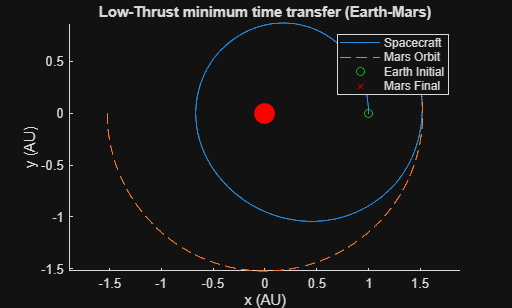


% Trajectory simulation
time = linspace(t0,tfCalc,1000);
X0 = [r0; v0; lamd0Calc];
options = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
[~, X] = ode45(@(t, X) spacecraftODE(t,X,mu,uMax), time, X0, options);
rxt = X(:,1);
ryt = X(:,2);
posMarst = zeros(2, length(time));
for i = 1:length(time)
    posMarst(:,i) = posMars(time(i));
end

% Control Extraction
lamdv = X(:,7:8);
u = zeros(size(lamdv));
for i = 1:size(lamdv,1)
    u(i,:) = (-uMax * lamdv(i,:) / norm(lamdv(i,:)));
end
ux = u(:,1);
uy = u(:,2);
uMag = sqrt(ux.^2 + uy.^2);

% Costate Extraction
lamdrx = X(:,5);
lamdry = X(:,6);
lamdvx = X(:,7);
lamdvy = X(:,8);

% Hamiltonian Delta
H = zeros(length(time),1);
for i = 1:length(time)
    r = X(i,1:2)';
    v = X(i,3:4)';
    lamdr = X(i,5:6)';
    lamdv = X(i,7:8)';
    ui = -uMax * (lamdv / norm(lamdv));
    H(i) = 1 + lamdr'*v + lamdv'*( -mu*r/norm(r)^3 + ui );
end
deltaH = H - H(1);

% PLOTS
figure
hold on
plot(rxt, ryt)
plot(posMarst(1,:), posMarst(2,:),'--', 'MarkerSize', 0.1)
plot(r0(1), r0(2), 'go', posMarst(1,end), posMarst(2,end), 'rx')
plot(0,0, 'ro', 'MarkerSize', 15, 'MarkerFaceColor','r')
axis equal
title("Low-Thrust minimum time transfer (Earth-Mars)")
xlabel("x (AU)")
ylabel("y (AU)")
legend('Spacecraft', 'Mars Orbit', 'Earth Initial', 'Mars Final')
hold off

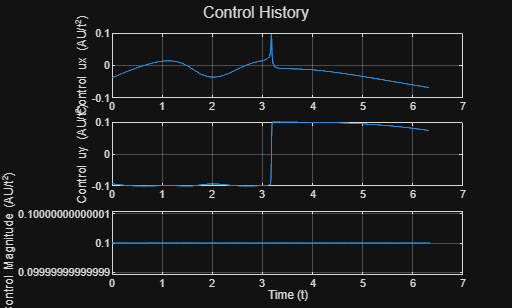


figure
hold on
subplot(3,1,1)
sgtitle("Control History")
plot(time,ux)
ylabel('Control ux (AU/t^2)')
grid on
subplot(3,1,2)
plot(time,uy)
ylabel('Control uy (AU/t^2)')
grid on
subplot(3,1,3)
plot(time, uMag)
ylabel('Control Magnitude (AU/t^2)')
xlabel('Time (t)')
grid on
hold off

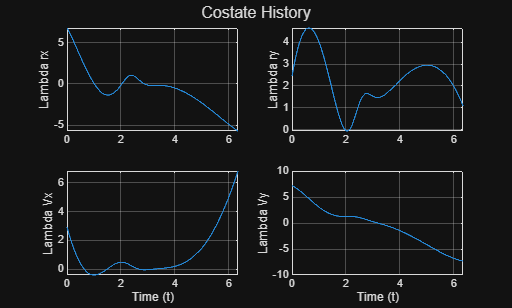


figure
hold on
sgtitle("Costate History")
subplot(2,2,1)
plot(time, lamdrx)
ylabel('Lambda rx')
grid on
subplot(2,2,2)
plot(time, lamdry)
ylabel('Lambda ry')
grid on
subplot(2,2,3)
plot(time, lamdvx)
ylabel('Lambda Vx')
grid on
xlabel('Time (t)')
subplot(2,2,4)
plot(time, lamdvy)
ylabel('Lambda Vy')
grid on
xlabel('Time (t)')
hold off

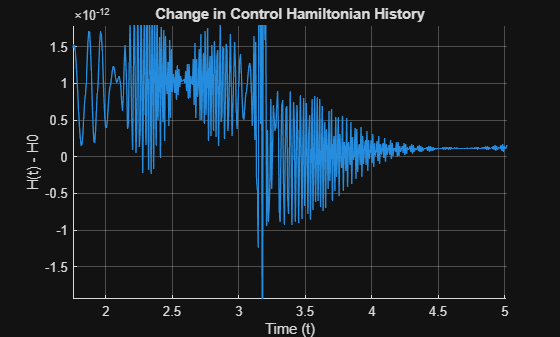


figure
hold on
plot(time,deltaH)
xlabel('Time (t)')
ylabel('H(t) - H0')
grid on
title("Change in Control Hamiltonian History")
hold off

## Different initial conditions

lamd0Correct = [];
lamd0Fail = [];
for N = 1:20
    lamd0Init = unifrnd(-10,10,4,1);
    tf = unifrnd(5,10,1,1);
    try
        Z0 = [lamd0Init; tf];
        options = optimoptions('fsolve','FunctionTolerance', 1e-8, 'StepTolerance',1e-12, 'MaxFunctionEvaluations', 500); % optimization options
        [lamd0Calc, fval, exitflag] = fsolve(@(Z) shooting(Z, posMars, t0, r0, v0, uMax, mu, velMars), Z0, options);
        lamd0Calc = shot(1:4); % CALCULATED INITIAL COSTATE VECTOR
        tfCalc = shot(5); % Calculated FINAL TIME
    catch
        lamd0Fail(:,end+1) = lamd0Init;
        continue
    end
        % Trajectory simulation
        time = linspace(t0,tfCalc,1000);
        X0 = [r0; v0; lamd0Calc];
        options = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
        [~, X] = ode45(@(t, X) spacecraftODE(t,X,mu,uMax), time, X0, options);
        rxt = X(:,1);
        ryt = X(:,2);
        posMarst = zeros(2, length(time));
        for i = 1:length(time)
            posMarst(:,i) = posMars(time(i));
        end
        
        % Control Extraction
        lamdv = X(:,7:8);
        u = zeros(size(lamdv));
        for i = 1:size(lamdv,1)
            u(i,:) = (-uMax * lamdv(i,:) / norm(lamdv(i,:)));
        end
        ux = u(:,1);
        uy = u(:,2);
        uMag = sqrt(ux.^2 + uy.^2);
        
        % Costate Extraction
        lamdrx = X(:,5);
        lamdry = X(:,6);
        lamdvx = X(:,7);
        lamdvy = X(:,8);
        
        % Hamiltonian Delta
        H = zeros(length(time),1);
        for i = 1:length(time)
            r = X(i,1:2)';
            v = X(i,3:4)';
            lamdr = X(i,5:6)';
            lamdv = X(i,7:8)';
            ui = -uMax * (lamdv / norm(lamdv));
            H(i) = 1 + lamdr'*v + lamdv'*( -mu*r/norm(r)^3 + ui );
        end
        deltaH = H - H(1);
        threshold = 1;
        aboveThresh = any(abs(deltaH) > threshold);
        if (exitflag > 0) && (aboveThresh == 0)
            lamd0Correct(:,end+1) = lamd0Init;
        else
            lamd0Fail(:,end+1) = lamd0Init;
        end
end


Solver stopped prematurely.

fsolve stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 5.000000e+02.


Solver stopped prematurely.

fsolve stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 5.000000e+02.


Solver stopped prematurely.

fsolve stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 5.000000e+02.


Equation solved.

f


lamd0Correct

lamd0Correct =     3.0938   -7.7918    8.4711   -6.9981    8.5372    5.2769    8.4542
   -9.4771   -5.6671   -9.7449    9.8261   -9.8341    6.1102   -3.5935
    5.7155    6.2204   -2.4568   -1.4588    6.4926   -7.9149    7.1509
    8.4513   -7.2268   -6.6438    9.1074    5.3467   -0.6048   -4.8031


lamd0Fail

lamd0Fail =    -1.0425    2.8186   -8.3944    6.6802   -4.8120    9.8781    5.4531    5.9597   -7.9668    2.8841    1.6178   -5.4469   -6.2346
    4.1928    6.1723   -2.7906   -7.3729   -5.7396    2.0896    4.8813    3.1116   -9.2146   -8.6411    0.8052    8.3908    5.1839
    8.8866    7.0674    6.5781    5.1957    0.4463    8.8982   -1.1419   -9.3533    8.6646   -5.8418    4.1088    2.8400   -9.3662
   -6.5176   -2.0376   -5.7078    8.5147   -2.0529   -0.1912   -8.9400    1.1413    9.4318   -9.2079   -9.8994   -7.8936    2.8468
